### System states

% 

### Parameters

% Initialzization
% vehicle parameters



### Prediction horizon /Control horizon/ Sample time

Np = 7;  % prediction horizon
Nc = 3; % control horizon
ts=0.05;; % sample time

### Reference

%% Preview information
socref=0.5;         % 電池參考容量50%
Pmref=8;            % 馬達總功率參考
cb=20;              % 額定電池容量kwh
cfc=20;             % 額定燃料電池容量kwh
yref=socref*ones(Np,1);
Pm=Pmref*ones(Nc,1);
%input
xk=[0.7 ;0.7];      %SOC當下
%wk=Pm;             %demen power
%Rs_zeros = zeros(Np,1);

## Model



A = [1 0;
    0 1]

A =      1     0
     0     1


B = [-ts/(cb*3600);ts/(cfc*3600)]

B = 1.0e-06 *

   -0.6944
    0.6944


D=[ts/(cb*3600);0]

D = 1.0e-06 *

    0.6944
         0


% discretization
%Ad = eye(8) + Ts*A
%Bd = Ts*B

% output matrix
H= [1 0]%[1 zeros(1,7)];

H =      1     0


%phi = A;
%gamma = B;


%phi = Ad;
%gamma = Bd;

## 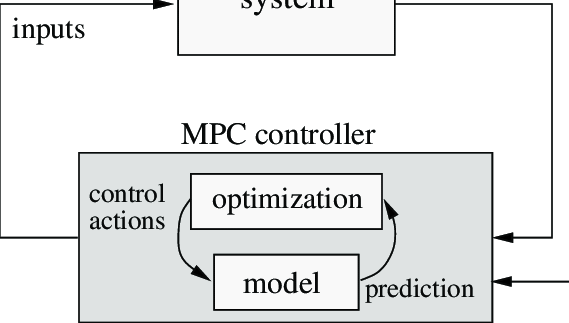

## Prediction model

% MPC initialization
NInp = 1;           %輸入量  ex soc*2
NState = 2;         %狀態量  ex power*1

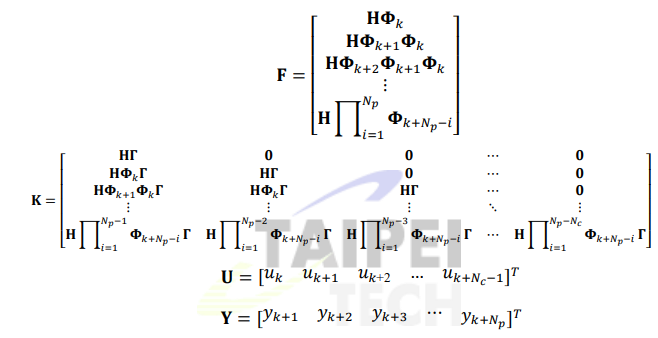

F = zeros(Np,NState);
% F1 = zeros(Np,wr);
K = zeros(Np,Nc*NInp);
% K1 = zeros(Np,Nc*NInp);


buff = zeros(Np,NInp);
for j = 1:Np
    F(j,1:NState)=H*A^j;
    buffK(j,1:NInp) = H*(phi^(j-1))*B;
    buffG(j,1:NInp) = H*(phi^(j-1))*D;
end

for i = 1:Nc
    K(i:Np,(1+(NInp)*(i-1):NInp*i)) = buffK(1:Np+1-i,:);
    G(i:Np,(1+(NInp)*(i-1):NInp*i)) = buffG(1:Np+1-i,:);
end

F

F =      1     0
     1     0
     1     0
     1     0
     1     0
     1     0
     1     0


K

K = 1.0e-06 *

   -0.6944         0         0
   -0.6944   -0.6944         0
   -0.6944   -0.6944   -0.6944
   -0.6944   -0.6944   -0.6944
   -0.6944   -0.6944   -0.6944
   -0.6944   -0.6944   -0.6944
   -0.6944   -0.6944   -0.6944


G

G = 1.0e-06 *

    0.6944         0         0
    0.6944    0.6944         0
    0.6944    0.6944    0.6944
    0.6944    0.6944    0.6944
    0.6944    0.6944    0.6944
    0.6944    0.6944    0.6944
    0.6944    0.6944    0.6944


### Constraints

*ignore this section first

%% MPC constraints
C1 = ones(Nc,1);
C2 = tril(ones(Nc));
% amplitude constraint on control signal
umin = [0];
umax = [10];
Umin = repmat(umin,Nc,1);
Umax = repmat(umax,Nc,1);


M2=[-eye(Nc*NInp); eye(Nc*NInp)];
N2 = [-Umin; Umax];

A_cons = M2;            %係數矩陣
b_cons = N2;            %限制矩陣

### Weighting

%% Command calculation
r_max = 1*pi/180;
beta_max = 10*pi/180;
Trq_max = 100;


w_r = 1 %/r_max^2;

w_r = 1

w_beta = 1/beta_max^2;
w_tm = 1/Trq_max^2;

W_WLR = diag(repmat(1,1,Nc))

W_WLR =      1     0     0
     0     1     0
     0     0     1


% error weighting
Q = w_r*eye(Np)

Q =      1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0
     0     0     0     0     0     1     0
     0     0     0     0     0     0     1


R_bar = w_tm*(W_WLR)

R_bar = 1.0e-04 *

    1.0000         0         0
         0    1.0000         0
         0         0    1.0000


h=500;
Bca=[1 0 0;0 1 0;0 0 1]

Bca =      1     0     0
     0     1     0
     0     0     1


### Control action

Global minimum

%u_op = inv( ((K')*Q*K+R_bar) )*(K')*Q*(Rs-F*Xk) % not satisfy constraints
%U_op=inv(((K')*Q*K+R_bar))%*(K')*Q*(yref-F*xk)
U_op=inv((K')*Q*K+R_bar+h*(Bca')*Bca)*((K')*Q*G*Pm+(K')*Q*(yref-F*xk)+h*(Bca')*Pm)

U_op =     8.0000
    8.0000
    8.0000


Y=F*xk+K*U_op+G*Pm

Y =     0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000
    0.7000


### Quadratic programming form

Transfrom problem to QP

H_qp =  (K')*Q*K+R_bar+h*(Bca')*Bca;
H_qp = (H_qp+H_qp')/2;   %對稱
f_qp = -((K')*Q*G*Pm+(K')*Q*(yref-F*xk)+h*(Bca')*Pm);

u = -H_qp\f_qp % Solution should be identical to u_op

u =     8.0000
    8.0000
    8.0000


u_star = u(1) % Actual control command being used

u_star = 8.0000

### Constraint command

x = quadprog(H_qp,f_qp,A_cons,b_cons) % satisfy constraints


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =     8.0000
    8.0000
    8.0000
